# Introduction to Filtering

An introduction to simple filters and their applications to diffferent types of signals.

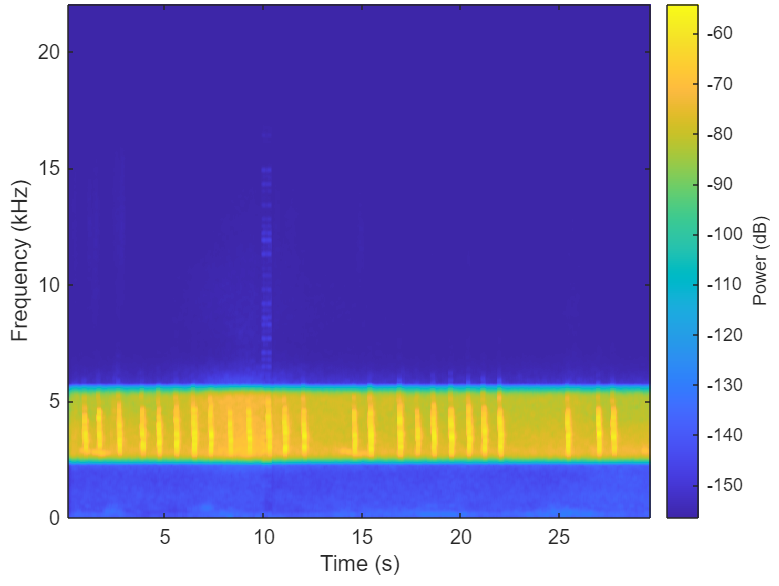

## Before you get started

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB® toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is filtering?

Filtering is a process that removes unwanted components from a signal. It can be used in a wide variety of applications, including audio, video, and digital communications. In this script, you will be working with multiple types of filters. Specific examples of where these filters can be useful include reducing noise to enhance the quality of audio recordings, sharpening edges to improve the visual quality of images, and removing interference to ensure accurate monitoring for medical devices.

## z-Axis angular velocity data

For the first part of this script, the data you will be working with is z-axis angular velocity data recorded by a phone during a morning commute in a car. In this case, the z-axis is the axis perpendicular to the road, meaning that this signal measures the velocity of the car perpendicular to the road. This data can provide information regarding bumps and road vibrations.

  **Try**. Use the button below to load and visualize the signal:

 

CommuteData = load("CommuteHome.mat");
CommuteSignal = CommuteData.AngularVelocity.Z;
CommuteSamplingFrequency = 10;

plot((1 / CommuteSamplingFrequency) * 1:length(CommuteSignal), CommuteSignal);
title("z-Axis Velocity");
xlabel("Time (Seconds)");
ylabel("Amplitude");

 **Reflect**. Are you able to gain much information from looking at this signal? How might you be able to better visually understand this data?

## Smoothing filters

One common application of filters is *smoothing* data. Smoothing is a process that can help to remove *noise*, or unwanted variation, from a signal in order to make the important patterns in the data more recognizable. In the case of a signal such as the one you visualized above, a smoothing filter can literally make the signal appear *smoother*. In the following section, you will learn about one particular smoothing filter, how it works, and how you can apply it to the z-axis velocity signal above.

### Savitzky-Golay filters

One common type of smoothing filter is called a *Savitzky-Golay filter*. At a high level, Savitzky-Golay filters work by fitting successive subsets of adjacent data points with a polynomial and replacing the central point in the subset with the central point of the polynomial fit for said subset. The specific steps for creating and applying a Savitzky-Golay filter are as follows:

- Choose the polynomial order. Frequently, low-order polynomials are used to avoid overfitting and introducing artifacts into the smoothed signal.

- Choose the window size. This will control how many data points are used for each polynomial fit. The window size must be odd so that it is symmetric around the point being estimated, and it should be significantly smaller than the size of the data set so that too much data is not lost.

- Fit a polynomial to the data in the window. This is typically done using the *least-squares method*, which minimizes the sum of the squares of the differences between the data points and the values predicted by the polynomial.

- Evaluate the polynomial at the central point. This value will be used as the smoothed value for this central point.

- Slide the window across the data. In other words, repeat steps 3 and 4 for each data point until the end of the data set is reached.

### Savitzky-Golay example

** Demonstration**. Let's walk through a simple example of how a Savitzky-Golay filter works. We'll start by plotting 15 random data points which will serve as our data set.

  **Try**. Use the button below to plot the data:

 

% Set seed for random number generation
rng(3);
YVals = rand(1,15);
XVals = 1:15;
plot(XVals, YVals, '-', Marker='.', MarkerSize=30, SeriesIndex=1);
ylim([0 1]);
xlim([0 16]);
xlabel('X');
ylabel('Y');
title("Savitzky-Golay Example");

For this example, we will be using a first-order polynomial, which is a linear fit, and we will be using a window size of 3. This means that a subset of 3 data points will be used for each polynomial fit.

Now that our parameters have been defined, let's execute step 3 of the process outlined above by fitting a first-order polynomial to our first window of data points. We will start with the second point in the data set, since the first point does not have enough neighbors to fit a polynomial using our predefined window size of 3.

  **Try**. Use the button below to visualize this step:

 

Order = 1;
Window = 3;
Coefs = polyfit(XVals(1:3), YVals(1:3), Order);
FitVals = polyval(Coefs, XVals(1:3));

plot(XVals, YVals, '-', Marker='.', MarkerSize=30, SeriesIndex=1);
ylim([0 1]);
xlim([0 16]);
xlabel('X');
ylabel('Y');
title("Savitzky-Golay Example");
hold on;
WindowVals = scatter(XVals(1:3), YVals(1:3), 100, 'filled', SeriesIndex=2);
PolyPlot = plot(XVals(1:3), FitVals, SeriesIndex=2);
legend([WindowVals PolyPlot], ["Values within window", "Fitted polynomial"]);
hold off;

Now that you've seen how step 3 works, let's execute step 4 by evaluating the fitted polynomial at its central point.

  **Try**. Use the button below to visualize this step:

 

NewVals = zeros(1,13);
NewVals(1) = FitVals(2);

plot(XVals, YVals, '-', Marker='.', MarkerSize=30, SeriesIndex=1);
ylim([0 1]);
xlim([0 16]);
xlabel('X');
ylabel('Y');
title("Savitzky-Golay Example");
hold on;
NewValPlot = scatter(XVals(2), NewVals(1), 100, 'filled', SeriesIndex=3);
PolyPlot = plot(XVals(1:3), FitVals, SeriesIndex=2);
legend([NewValPlot PolyPlot], ["New value at X=2", "Fitted polynomial"]);
hold off;

Now all that's left to do is to repeat steps 3 and 4 for the rest of the points in the signal!

  **Try**. Use the button below to iterate through the rest of the process and view an animation which shows it step by step:

 

OrigValsPlot = plot(XVals, YVals, '-', Marker='.', MarkerSize=30, SeriesIndex=1);
ylim([0 1]);
xlim([0 16]);
xlabel('X');
ylabel('Y');
title("Savitzky-Golay Example");
hold on;
scatter(XVals(2), NewVals(1), 100, 'filled', SeriesIndex=3);
for i = 3:14
    Coefs = polyfit(XVals((i-1):(i+1)), YVals((i-1):(i+1)), Order);
    FitVals = polyval(Coefs, XVals((i-1):(i+1)));
    
    plot(XVals, YVals, '-', Marker='.', MarkerSize=30, SeriesIndex=1);
    ylim([0 1]);
    xlim([0 16]);
    title("Savitzky-Golay Example");
    WindowVals = scatter(XVals((i-1):(i+1)), YVals((i-1):(i+1)), 100, 'filled', SeriesIndex=2);
    PolyPlot = plot(XVals((i-1):(i+1)), FitVals, SeriesIndex=2);
    legend([WindowVals PolyPlot], ["Values within window", "Fitted polynomial"]);

    drawnow;

    NewVals(i-1) = FitVals(2);

    NewValPlot = scatter(XVals(i), NewVals(i-1), 100, 'filled', SeriesIndex=3);

    delete(PolyPlot);
    delete(WindowVals);
end

NewValsPlot = plot(XVals(2:14), NewVals, '-', Marker='.', MarkerSize=30, SeriesIndex=3);
legend([OrigValsPlot NewValsPlot], ["Original signal", "Smoothed signal"]);
hold off;

## Applying Savitzky-Golay to z-axis velocity data

Now that you have an understanding of how Savitzky-Golay filters work, let's try to apply one to the z-axis velocity data from earlier in this script.

  **Try**. First, use the button below to visualize the data as a reminder of how it looks:

 

plot((1 / CommuteSamplingFrequency) * 1:length(CommuteSignal), CommuteSignal);
title("z-Axis Velocity");
xlabel("Time (Seconds)");
ylabel("Amplitude");

  **Try**. Now, use the controls below to apply Savitzky-Golay filters with different parameters to the z-axis velocity data. Try to find a combination of parameters that smooths the data such that you are able to more clearly recognize important patterns and fluctuations in the signal. Observe which combinations of parameters work well and which do not, and consider why certain combinations yield different results than others. Recall the constraints for the window size as described in step 2 of the algorithm

FilterOrder = 1;
WindowSize = 1;
 

try
    FilteredSignal = sgolayfilt(CommuteSignal, FilterOrder, WindowSize);
    plot((1/CommuteSamplingFrequency) * 1:length(FilteredSignal), FilteredSignal);
    title("Filtered z-Axis Velocity");
    xlabel("Time (Seconds)");
    ylabel("Amplitude");
catch ME
    if ME.identifier == "signal:sgolayfilt:InvalidRangeDegree"
        disp("Filter order must be less than window size");
    end
end

## Birdsong data

Throughout the rest of this script, the data you will be working with is a clip of a raw recording of birds chirping in a backyard.

  **Try**. Use the controls below to load the data and listen to the recording:

 

[Signal, SamplingFrequency] = audioread("BirdSong.m4a");
Signal = Signal(236906:673812,2);
disp("Data loaded");

 
if ~strcmpi(getenv("CI"), "true")
    UnfilteredPlayer = audioplayer(Signal, SamplingFrequency);
    play(UnfilteredPlayer);
end

 **Reflect**. How might you want to manipulate this recording using filters?

## Visualizing signals

In order to understand a signal and its components, it is useful to visualize the signal. Let's explore four different ways to view signals: the *time domain**,* the *FFT*, the *power spectrum**,* and the *spectrogram*.

### The time domain

Signals can be visualized in the *time domain* by plotting time on the x-axis and amplitude on the y-axis. This is how you visualized the z-axis velocity data in the first part of this script; it is useful to see how the amplitude of a signal varies over time.

  **Try**. Use the button below to view the birdsong signal in the time domain:

 
plot((1 / SamplingFrequency) * (1:length(Signal)), Signal);
title("Birdsong Signal");
xlabel("Time (Seconds)");
ylabel("Amplitude");

 **Reflect**. Is this visualization useful for this data? Can you think of any other types of signals that would be helpful to view in the time domain?

### The Fast Fourier Transform (FFT)

Signals can be visualized in the frequency domain by using the *FFT*, which entails plotting frequency on the x-axis and amplitude on the y-axis. It is particularly useful for identifying the presence of different frequencies in a signal.

  **Try**. Use the button below to view the FFT plot of the birdsong signal:

  **Pro-tip**. Fourier transforms are a widely used concept in signal processing. To learn more about them, work through [this Fourier Analysis courseware module](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Fourier-Analysis&project=fourier-analysis.prj) and watch [this introductory video about the FFT](https://www.youtube.com/watch?v=QmgJmh2I3Fw).

 

warning('off');

y = fft(Signal);
p2 = abs(y / length(Signal));
p1 = p2(1:(length(Signal)/2)+1);
p1(2:end-1) = 2 * p1(2:end-1);
f = SamplingFrequency / length(Signal) * (0:(length(Signal) / 2));
plot(f/1000, p1);
title("FFT of Birdsong Signal");
xlabel("Frequency (kHz)");
ylabel("Amplitude");

### The power spectrum

Signals can be visualized in the frequency domain by looking at the *power spectrum* of the signal, which entails plotting frequency on the x-axis and power on the y-axis.

  **Try**. Use the button below to view the power spectrum of the birdsong signal:

  **Pro-tip**. The power spectrum can be an important tool in signal processing. To learn more about it and how it relates to the FFT, check out [this introductory video about the power spectrum](https://www.youtube.com/watch?v=pfjiwxhqd1M).

 
[p, f] = pspectrum(Signal, SamplingFrequency);
p = 10 * log10(p);
plot(f/1000, p);
title("Power Spectrum of Birdsong Signal");
xlabel("Frequency (kHz)");
ylabel("Power Spectrum (dB)");

### The spectrogram

Signals can be visualized in the time-frequency domain by looking at the *spectrogram* of the signal, which entails plotting time on the x-axis and frequency on the y-axis, with the power represented by colors. This is helpful as a way of visualizing time, frequency, and power all at the same time.

  **Try**. Use the button below to view the spectrogram of the birdsong signal:

 
pspectrum(Signal, SamplingFrequency, 'spectrogram');
title("Spectrogram of Birdsong Signal");

#### Understanding the spectrogram

To give context to the spectrogram, listen to the birdsong recording again and pay close attention to how it lines up with the spectrogram. What do you notice?

  **Try**. Use the button below to play the birdsong recording.

 
if ~strcmpi(getenv("CI"), "true")
    UnfilteredPlayer = audioplayer(Signal, SamplingFrequency);
    play(UnfilteredPlayer);
end

 **Exercise 1. **Based on these different visualizations of the birdsong signal, what is the approximate frequency range of the bird chirps?

Bottom = 0;
Top = 0;
 
CheckExercise1(Bottom, Top);

 **Exercise 2. **For each type of visualization listed below, check the box of each type of information that visualization includes.

*Time domain:*

vis = 'time domain';
time = false;
amplitude = false;
frequency = false;
power = false;
 
CheckExercise2(vis, time, amplitude, frequency, power);

*FFT:*

vis = 'fft';
time = false;
amplitude = false;
frequency = false;
power = false;
 
CheckExercise2(vis, time, amplitude, frequency, power);

*Power spectrum:*

vis = 'power spectrum';
time = false;
amplitude = false;
frequency = false;
power = false;
 
CheckExercise2(vis, time, amplitude, frequency, power);

*Spectrogram:*

vis = 'spectrogram';
time = false;
amplitude = false;
frequency = false;
power = false;
 
CheckExercise2(vis, time, amplitude, frequency, power);

## Types of filters

There are many different types of filters to be used in many different scenarios. In the following sections, you will learn about some of the most common ones and how they can be applied.

*Your goal as you work through the following sections will be to use these filters to isolate the bird chirps from the background noise in the birdsong signal.*

### Highpass filters

Highpass filters, as the name suggests, keep the high-frequency components of a signal, which are higher than the specified *passband frequency*, while *attenuating*, or limiting the strength of, the low-frequency components which are lower than the passband frequency. 

  **Try**. Use the controls below to apply highpass filters with different passband frequencies to the birdsong data and observe the results by visualizing the filtered signal in the different domains and comparing the filtered recording to the unfiltered recording. Keep in mind the goal of isolating the bird chirps from the background noise.

PassbandFrequency = 0.1 * 1000;
VisualizationDomain = "time domain";
 

HighpassSignal = highpass(Signal, PassbandFrequency, SamplingFrequency);

if VisualizationDomain == 'time domain'
    plot((1 / SamplingFrequency) * (1:length(HighpassSignal)), HighpassSignal);
    title("Filtered Birdsong Signal");
    xlabel("Time (Seconds)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'FFT'
    y = fft(HighpassSignal);
    p2 = abs(y / length(HighpassSignal));
    p1 = p2(1:(length(HighpassSignal)/2)+1);
    p1(2:end-1) = 2 * p1(2:end-1);
    f = SamplingFrequency / length(HighpassSignal) * (0:(length(HighpassSignal) / 2));
    plot(f/1000, p1);
    title("FFT of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'power spectrum'
    [p, f] = pspectrum(HighpassSignal, SamplingFrequency);
    p = 10 * log10(p);
    plot(f/1000, p);
    title("Power Spectrum of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Power Spectrum (dB)");
elseif VisualizationDomain == 'spectrogram'
    pspectrum(HighpassSignal, SamplingFrequency, 'spectrogram');
    title("Spectrogram of Filtered Birdsong Signal");
end

 

try
    if ~strcmpi(getenv("CI"), "true")
        HighpassPlayer = audioplayer(HighpassSignal, SamplingFrequency);
    end
    pspectrum(HighpassSignal, SamplingFrequency, 'spectrogram');
    hold on;
    title("Spectrogram of Filtered Birdsong Signal");
    Line = xline(0, LineWidth=2, SeriesIndex=7);
    if ~strcmpi(getenv("CI"), "true")
        play(HighpassPlayer);
    end
    pause(0.1);
    for i = 1:100
        Line.Value = i * 0.1;
        pause(0.1);
    end
    hold off;
catch ME
    if ME.identifier == "MATLAB:UndefinedFunction"
        disp("Visualize the filtered signal before playing the recording");
    end
end

 

if ~strcmpi(getenv("CI"), "true")
    UnfilteredPlayer = audioplayer(Signal, SamplingFrequency);
end
pspectrum(Signal, SamplingFrequency, 'spectrogram');
hold on;
title("Spectrogram of Unfiltered Birdsong Signal");
Line = xline(0, LineWidth=2, SeriesIndex=7);
if ~strcmpi(getenv("CI"), "true")
    play(UnfilteredPlayer);
end
pause(0.1);
for i = 1:100
    Line.Value = i * 0.1;
    pause(0.1);
end
hold off;

### Lowpass filters

Lowpass filters, on the other hand, keep the low-frequency components of a signal while attenuating the high-frequency components.

  **Try**. Use the controls below to apply lowpass filters with different passband frequencies to the birdsong data and observe the results by visualizing the filtered signal in the different domains and comparing the filtered recording to the unfiltered recording. Keep in mind the goal of isolating the bird chirps from the background noise.

PassbandFrequency = 0.1 * 1000;
VisualizationDomain = "time domain";
 

LowpassSignal = lowpass(Signal, PassbandFrequency, SamplingFrequency);

if VisualizationDomain == 'time domain'
    plot((1 / SamplingFrequency) * (1:length(LowpassSignal)), LowpassSignal);
    title("Filtered Birdsong Signal");
    xlabel("Time (Seconds)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'FFT'
    y = fft(LowpassSignal);
    p2 = abs(y / length(LowpassSignal));
    p1 = p2(1:(length(LowpassSignal)/2)+1);
    p1(2:end-1) = 2 * p1(2:end-1);
    f = SamplingFrequency / length(LowpassSignal) * (0:(length(LowpassSignal) / 2));
    plot(f/1000, p1);
    title("FFT of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'power spectrum'
    [p, f] = pspectrum(LowpassSignal, SamplingFrequency);
    p = 10 * log10(p);
    plot(f/1000, p);
    title("Power Spectrum of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Power Spectrum (dB)");
elseif VisualizationDomain == 'spectrogram'
    pspectrum(LowpassSignal, SamplingFrequency, 'spectrogram');
    title("Spectrogram of Filtered Birdsong Signal");
end

 

try
    if ~strcmpi(getenv("CI"), "true")
        LowpassPlayer = audioplayer(LowpassSignal, SamplingFrequency);
    end
    pspectrum(LowpassSignal, SamplingFrequency, 'spectrogram');
    hold on;
    title("Spectrogram of Filtered Birdsong Signal");
    Line = xline(0, LineWidth=2, SeriesIndex=7);
    if ~strcmpi(getenv("CI"), "true")
        play(LowpassPlayer);
    end
    pause(0.1);
    for i = 1:100
        Line.Value = i * 0.1;
        pause(0.1);
    end
    hold off;
catch ME
    if ME.identifier == "MATLAB:UndefinedFunction"
        disp("Visualize the filtered signal before playing the recording");
    end
end

 

if ~strcmpi(getenv("CI"), "true")
    UnfilteredPlayer = audioplayer(Signal, SamplingFrequency);
end
pspectrum(Signal, SamplingFrequency, 'spectrogram');
hold on;
title("Spectrogram of Unfiltered Birdsong Signal");
Line = xline(0, LineWidth=2, SeriesIndex=7);
if ~strcmpi(getenv("CI"), "true")
    play(UnfilteredPlayer);
end
pause(0.1);
for i = 1:100
    Line.Value = i * 0.1;
    pause(0.1);
end
hold off;

 **Reflect**. How successful have you been in isolating the bird chirps from the background noise using highpass and lowpass filters? If you have struggled, you may be interested in the next type of filter...

### Bandpass filters

Bandpass filters allow components within a specified range of frequencies to pass through, and attenuate all other components. These filters require two parameters: the upper and lower passband frequency limits to define the range of acceptable frequencies to pass through the filter.

  **Try**. Use the controls below to apply bandpass filters with different frequency ranges to the birdsong data and observe the results by visualizing the filtered signal in the different domains and comparing the filtered recording to the unfiltered recording. Keep in mind the goal of isolating the bird chirps from the background noise.

  **Pro-tip**. You won't be using it in this activity, but there is another type of filter called a *bandstop filter* that can be useful in many applications. As its name suggests, it does the opposite of a bandpass filter - while a bandpass filter allows frequencies in the specified range to *pass* through, a bandstop filter *stops* frequencies in the specified range from passing through.

LowerPassbandFrequency = 0.1 * 1000;
UpperPassbandFrequency = 0.1 * 1000;
VisualizationDomain = "time domain";
 

try
    BandpassSignal = bandpass(Signal, [LowerPassbandFrequency UpperPassbandFrequency], SamplingFrequency);
catch
    disp("Make sure your upper passband frequency is greater than your lower passband frequency.");
    return;
end

if VisualizationDomain == 'time domain'
    plot((1 / SamplingFrequency) * (1:length(BandpassSignal)), BandpassSignal);
    title("Filtered Birdsong Signal");
    xlabel("Time (Seconds)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'FFT'
    y = fft(BandpassSignal);
    p2 = abs(y / length(BandpassSignal));
    p1 = p2(1:(length(BandpassSignal)/2)+1);
    p1(2:end-1) = 2 * p1(2:end-1);
    f = SamplingFrequency / length(BandpassSignal) * (0:(length(BandpassSignal) / 2));
    plot(f/1000, p1);
    title("FFT of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Amplitude");
elseif VisualizationDomain == 'power spectrum'
    [p, f] = pspectrum(BandpassSignal, SamplingFrequency);
    p = 10 * log10(p);
    plot(f/1000, p);
    title("Power Spectrum of Filtered Birdsong Signal");
    xlabel("Frequency (kHz)");
    ylabel("Power Spectrum (dB)");
elseif VisualizationDomain == 'spectrogram'
    pspectrum(BandpassSignal, SamplingFrequency, 'spectrogram');
    title("Spectrogram of Filtered Birdsong Signal");
end

 

try
    if ~strcmpi(getenv("CI"), "true")
        BandpassPlayer = audioplayer(BandpassSignal, SamplingFrequency);
    end
    pspectrum(BandpassSignal, SamplingFrequency, 'spectrogram');
    hold on;
    title("Spectrogram of Filtered Birdsong Signal");
    Line = xline(0, LineWidth=2, SeriesIndex=7);
    if ~strcmpi(getenv("CI"), "true")
        play(BandpassPlayer);
    end
    pause(0.1);
    for i = 1:100
        Line.Value = i * 0.1;
        pause(0.1);
    end
    hold off;
catch ME
    if ME.identifier == "MATLAB:UndefinedFunction"
        disp("Visualize the filtered signal before playing the recording");
    end
end

 

if ~strcmpi(getenv("CI"), "true")
    UnfilteredPlayer = audioplayer(Signal, SamplingFrequency);
end
pspectrum(Signal, SamplingFrequency, 'spectrogram');
hold on;
title("Spectrogram of Unfiltered Birdsong Signal");
Line = xline(0, LineWidth=2, SeriesIndex=7);
if ~strcmpi(getenv("CI"), "true")
    play(UnfilteredPlayer);
end
pause(0.1);
for i = 1:100
    Line.Value = i * 0.1;
    pause(0.1);
end
hold off;

 **Exercise 3. **Once you are satisfied that your filter has filtered out as much background noise as possible while keeping the bird chirps, use the button below to submit your solution.

 
CheckExercise3(LowerPassbandFrequency/1000, UpperPassbandFrequency/1000);

 **Reflect**. In what other scenarios could you imagine these filtering techniques being useful?

## **Filter design**

To explore more complex types of filters and how they can be applied to different types of signals, move on to [FilterDesign.mlx](matlab:open('Scripts/FilterDesign.mlx')).

## Local Helper Functions

**CheckExercise1**

function CheckExercise1(Bottom, Top)
    if (Bottom >= 2 && Bottom <= 4) && (Top >= 4 && Top <= 6)
        disp("Great job!");
    else
        disp("Try again. Hint: Try to identify the distinct bird chirps in the spectrogram.");
    end
end

**CheckExercise2**

function CheckExercise2(vis, time, amplitude, frequency, power)
    switch vis
        case 'time domain'
            if time == true && amplitude == true && frequency == false && power == false
                disp("Great job!");
            else
                disp("Try again. If you're struggling, try going back to the previous section to read about each visualization type.");
            end
        case 'fft'
            if time == false && amplitude == true && frequency == true && power == false
                disp("Great job!");
            else
                disp("Try again. If you're struggling, try going back to the previous section to read about each visualization type.");
            end
        case 'power spectrum'
            if time == false && amplitude == false && frequency == true && power == true
                disp("Great job!");
            else
                disp("Try again. If you're struggling, try going back to the previous section to read about each visualization type.");
            end
        case 'spectrogram'
            if time == true && amplitude == false && frequency == true && power == true
                disp("Great job!");
            else
                disp("Try again. If you're struggling, try going back to the previous section to read about each visualization type.");
            end
    end
end

**CheckExercise3**

function CheckExercise3(LowerPassbandFrequency, UpperPassbandFrequency)
    if (LowerPassbandFrequency >= 2 && LowerPassbandFrequency <= 4) && (UpperPassbandFrequency >= 4 && UpperPassbandFrequency <= 6)
        disp("Great job!");
    else
        disp("Try again. Hint: Remember your answer from Exercise 1.");
    end
end